% Load all files - Each segment 10 min. 6 segments makes one hour (1-6, 7-12, 13-18)

load Patient_1_interictal_segment_0007.mat
load Patient_1_interictal_segment_0008.mat
load Patient_1_interictal_segment_0009.mat
load Patient_1_interictal_segment_0010.mat
load Patient_1_interictal_segment_0011.mat
load Patient_1_interictal_segment_0012.mat

load Patient_1_preictal_segment_0007.mat
load Patient_1_preictal_segment_0008.mat
load Patient_1_preictal_segment_0009.mat
load Patient_1_preictal_segment_0010.mat
load Patient_1_preictal_segment_0011.mat
load Patient_1_preictal_segment_0012.mat


% Set Data Variables

I_01_Data = interictal_segment_7.data;      % .data files gathered from .mat segment struct
I_02_Data = interictal_segment_8.data;
I_03_Data = interictal_segment_9.data;
I_04_Data = interictal_segment_10.data;
I_05_Data = interictal_segment_11.data;
I_06_Data = interictal_segment_12.data;

P_01_Data = preictal_segment_7.data;
P_02_Data = preictal_segment_8.data;
P_03_Data = preictal_segment_9.data;
P_04_Data = preictal_segment_10.data;
P_05_Data = preictal_segment_11.data;
P_06_Data = preictal_segment_12.data;


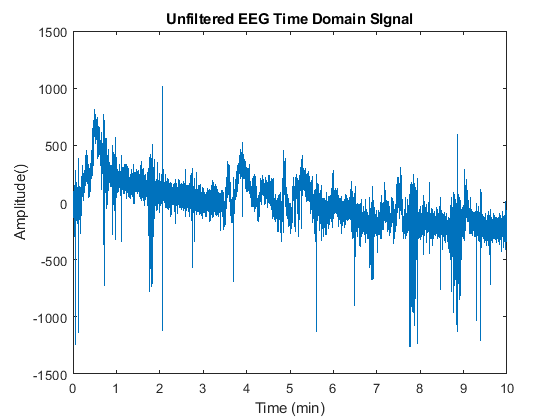

% Simple, Unfiltered data plot (Time Domain)

Channel = 10;                               % Pick data channel (1-15)
CurrentData = I_01_Data(Channel,:);         % Pick data set

length_data = length(CurrentData);
dt = (interictal_segment_7.data_length_sec / 60) / length_data;
t = (0:(length_data-1)) * dt;

plot(t, CurrentData)
xlabel('Time (min)'); ylabel('Amplitude()'); title('Unfiltered EEG Time Domain SIgnal');

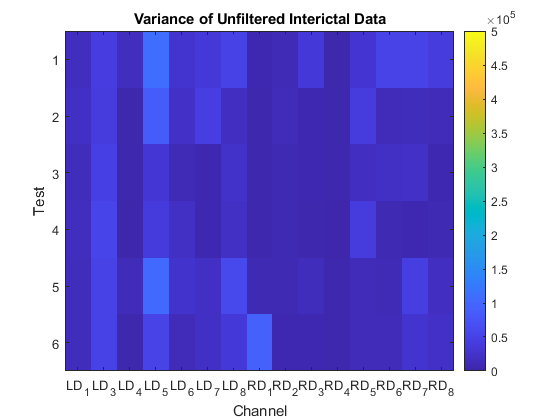

% Variances between all segments of interictal and preictal

I_Vars = zeros([6 15]);                     % Initialize empty matrix (6 segments x 15 channels)
for i=1:15                                  
    I_Vars(1,i) = var(I_01_Data(i,:));      
    I_Vars(2,i) = var(I_02_Data(i,:));
    I_Vars(3,i) = var(I_03_Data(i,:));
    I_Vars(4,i) = var(I_04_Data(i,:));
    I_Vars(5,i) = var(I_05_Data(i,:));
    I_Vars(6,i) = var(I_06_Data(i,:));
end

figure
image(I_Vars, 'CDataMapping','scaled')
caxis([0 500000])
colorbar
title('Variance of Unfiltered Interictal Data')
xlabel('Channel')
ylabel('Test')
xticks(1:15)
xticklabels(interictal_segment_9.channels)
yticklabels(1:6)

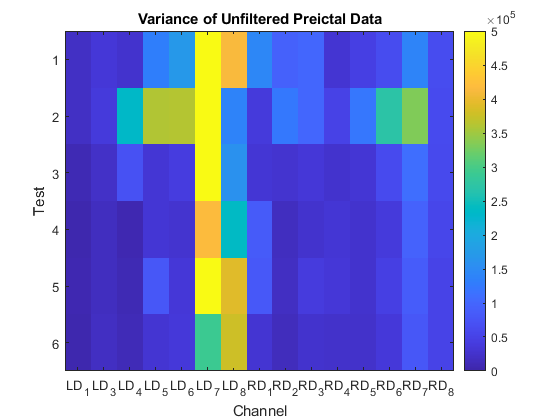


P_Vars = zeros([6 15]);
for i=1:15
    P_Vars(1,i) = var(P_01_Data(i,:));
    P_Vars(2,i) = var(P_02_Data(i,:));
    P_Vars(3,i) = var(P_03_Data(i,:));
    P_Vars(4,i) = var(P_04_Data(i,:));
    P_Vars(5,i) = var(P_05_Data(i,:));
    P_Vars(6,i) = var(P_06_Data(i,:));
end

figure
image(P_Vars, 'CDataMapping','scaled')
caxis([0 500000])
title('Variance of Unfiltered Preictal Data')
xlabel('Channel')
ylabel('Test')
xticks(1:15)
xticklabels(interictal_segment_9.channels)
yticklabels(1:6)
colorbar

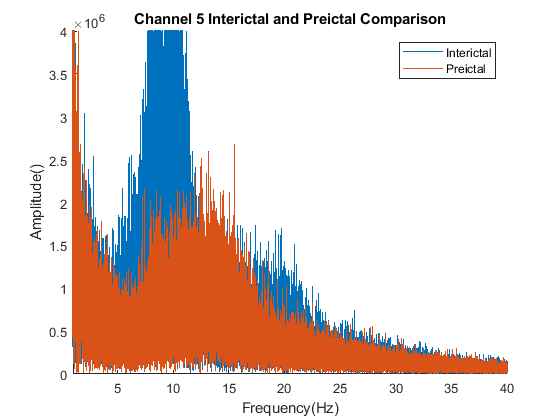

% Comparing Fourier of Interictal and Preictal

fs = interictal_segment_9.sampling_frequency;           % Sampling frequency from .mat struct
N = 3000000;                                            % Data set length
df = fs/N;                                              % Frequency Interval
freq = ((-N/2:(N/2)-1))*df;                             % Frequency Vector

Channel = 5;                                            % Pick data channel (1-15)
I_fft_data = fftshift(abs(fft(I_02_Data(Channel,:))));   % Pick interictal data set
P_fft_data = fftshift(abs(fft(P_02_Data(Channel,:))));   % Pick preictal data set

figure
hold on
plot(freq,I_fft_data)
plot(freq,P_fft_data)
fftComparison_title = sprintf('Channel %d Interictal and Preictal Comparison', Channel);
title(fftComparison_title)
legend('Interictal', 'Preictal')
xlim([1 40])
ylim([0 4000000])
xlabel('Frequency(Hz)'); ylabel('Amplitude()');
hold off

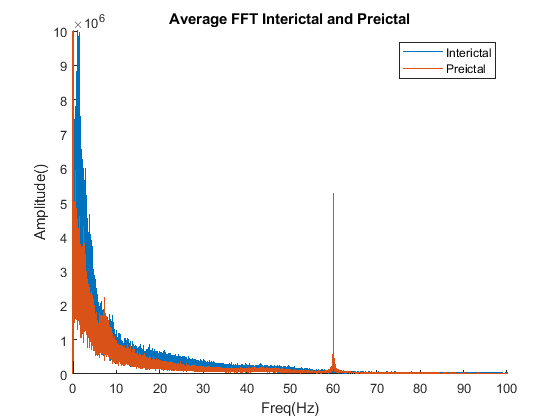


% Average Interictal Fourier Transform

Channel = 2;                                  % Pick data channel (1-15)

I_fft_01 = fftshift(abs(fft(I_01_Data(Channel,:))));    % fft of each segment with given channel
I_fft_02 = fftshift(abs(fft(I_02_Data(Channel,:))));
I_fft_03 = fftshift(abs(fft(I_03_Data(Channel,:))));
I_fft_04 = fftshift(abs(fft(I_04_Data(Channel,:))));
I_fft_05 = fftshift(abs(fft(I_05_Data(Channel,:))));
I_fft_06 = fftshift(abs(fft(I_06_Data(Channel,:))));

I_fft_avg = zeros(1,N);                       % Empty average fft matrix

for i=N/2:N                                   % Fill matrix, only using positive values
    I_fft_avg(1,i) = (I_fft_01(1,i) + I_fft_02(1,i)+ I_fft_03(1,i) + I_fft_04(1,i) + I_fft_05(1,i) + I_fft_06(1,i)) / 10;
end

%  Average Preictal Fourier Transform

fs = preictal_segment_7.sampling_frequency;
N = 3000000;
df = fs/N;
freq = ((-N/2:(N/2)-1))*df;

P_fft_01 = fftshift(abs(fft(P_01_Data(Channel,:))));
P_fft_02 = fftshift(abs(fft(P_02_Data(Channel,:))));
P_fft_03 = fftshift(abs(fft(P_03_Data(Channel,:))));
P_fft_04 = fftshift(abs(fft(P_04_Data(Channel,:))));
P_fft_05 = fftshift(abs(fft(P_05_Data(Channel,:))));
P_fft_06 = fftshift(abs(fft(P_06_Data(Channel,:))));

P_fft_avg = zeros(1,N);

for i=N/2:N
    P_fft_avg(1,i) = (P_fft_01(1,i) + P_fft_02(1,i)+ P_fft_03(1,i) + P_fft_04(1,i) + P_fft_05(1,i) + P_fft_06(1,i)) / 10;
end

% Plot Comparison Interictal FFT vs. Preictal FFT

figure
hold on
plot(freq, I_fft_avg)
plot(freq, P_fft_avg)
legend('Interictal', 'Preictal')
title("Average FFT Interictal and Preictal"); xlabel ('Freq(Hz)'); ylabel('Amplitude()');
xlim([0 100])
ylim([0 10000000])
hold off

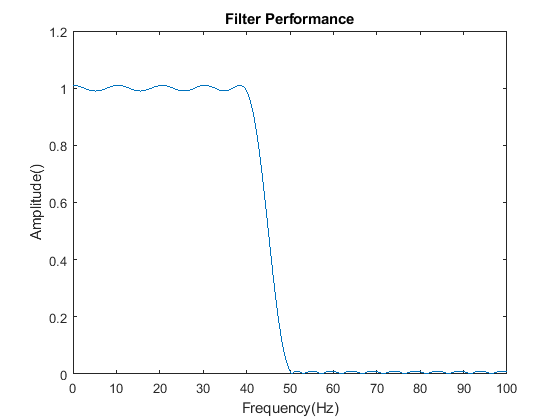

% LPF for any data set

lpFilt = designfilt('lowpassfir', 'FilterOrder',1000, 'PassbandFrequency',40, 'StopbandFrequency',50, 'SampleRate', 5000);
Channel = 1;                                    % Pick data channel (1-15)

unfiltered = P_01_Data(Channel,:);              % Pick data set
filtered = filtfilt(lpFilt, unfiltered);        % filtfilt fixes phase shift caused by filter

fft_unfiltered = fftshift(abs(fft(unfiltered)));
fft_filtered = fftshift(abs(fft(filtered)));

[h,f] = freqz(lpFilt,N,fs);
figure
plot(f,abs(h))
title('Filter Performance')
xlabel('Frequency(Hz)'); ylabel('Amplitude()');
xlim([0 100])

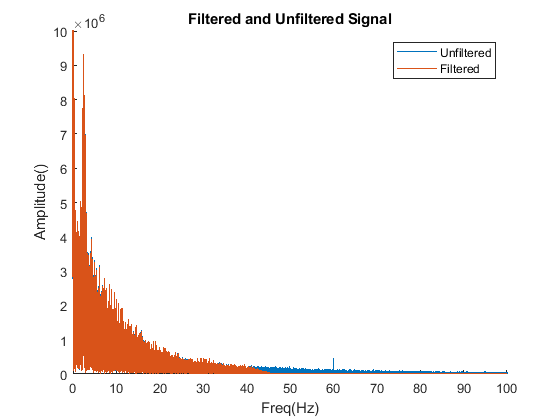


figure
hold on
plot(freq, fft_unfiltered)
plot(freq, fft_filtered)
xlim([0 100])
ylim([0 10000000])
title('Filtered and Unfiltered Signal'); xlabel('Freq(Hz)'); ylabel('Amplitude()');
legend('Unfiltered', 'Filtered')
hold off

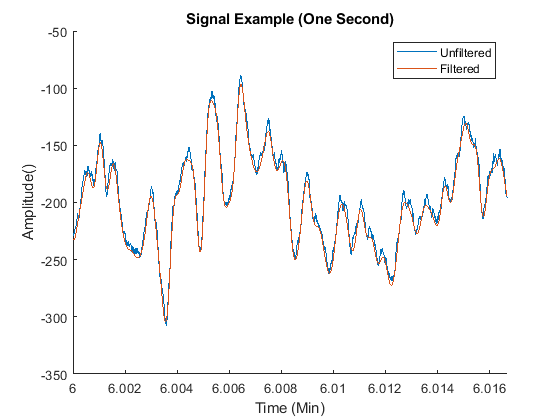


figure
hold on
plot(t,unfiltered)
plot(t,filtered)
legend('Unfiltered', 'Filtered')
title('Signal Example (One Second)')
xlim([6 (6+1/60)])
xlabel('Time (Min)'); ylabel('Amplitude()');
hold off

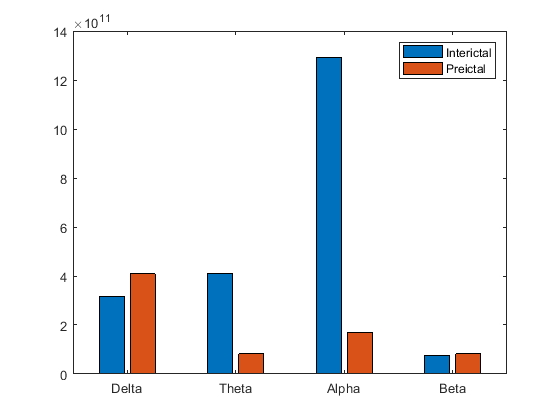

% Tests for brainwaves: Delta, Theta, Alpha, Beta

% Variance Bar graphs of brianwaves

var_vals = zeros(4,2);
x_names = categorical({'Delta','Theta','Alpha','Beta'});
x_names = reordercats(x_names,{'Delta','Theta','Alpha','Beta'});

x_names_str = ["Delta", "Theta", "Alpha", "Beta"];

delta_1 = find(freq == 1);
delta_2 = find(freq == 4) - 1;

theta_1 = find(freq == 4) + 1;
theta_2 = find(freq == 8) - 1;

alpha_1 = find(freq == 8);
alpha_2 = find(freq == 13);

beta_1 = find(freq == 13) + 1;
beta_2 = find(freq == 40);

bottom_bound = [delta_1, theta_1, alpha_1, beta_1];
top_bound = [delta_2, theta_2, alpha_2, beta_2];

for i = 1:4
    var_vals(i,1) = var(I_fft_data(1,bottom_bound(i):top_bound(i)));
end

for i = 1:4
    var_vals(i,2) = var(P_fft_data(1,bottom_bound(i):top_bound(i)));
end

figure
bar(x_names, var_vals)
legend('Interictal', 'Preictal')

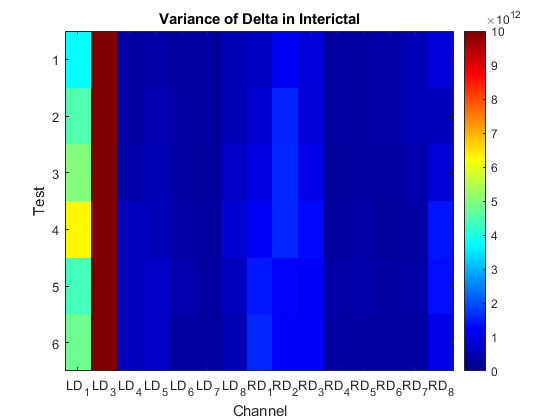


% FFT variance for any brainwave

brainWave = 1;                                           % 1=Delta, 2=Theta, 3=Alpha, 4=Beta

I_fft_Vars = zeros([6 15]);
for i=1:15
    fft_temp_01 = fftshift(abs(fft(I_01_Data(i,:))));
    fft_temp_02 = fftshift(abs(fft(I_02_Data(i,:))));
    fft_temp_03 = fftshift(abs(fft(I_03_Data(i,:))));
    fft_temp_04 = fftshift(abs(fft(I_04_Data(i,:))));
    fft_temp_05 = fftshift(abs(fft(I_05_Data(i,:))));
    fft_temp_06 = fftshift(abs(fft(I_06_Data(i,:))));
    
    I_fft_Vars(1,i) = var(fft_temp_01(1,bottom_bound(brainWave):top_bound(brainWave)));
    I_fft_Vars(2,i) = var(fft_temp_02(1,bottom_bound(brainWave):top_bound(brainWave)));
    I_fft_Vars(3,i) = var(fft_temp_03(1,bottom_bound(brainWave):top_bound(brainWave)));
    I_fft_Vars(4,i) = var(fft_temp_04(1,bottom_bound(brainWave):top_bound(brainWave)));
    I_fft_Vars(5,i) = var(fft_temp_05(1,bottom_bound(brainWave):top_bound(brainWave)));
    I_fft_Vars(6,i) = var(fft_temp_06(1,bottom_bound(brainWave):top_bound(brainWave)));
end

figure
image(I_fft_Vars, 'CDataMapping','scaled')
caxis([0 10000000000000])
colorbar
colormap(jet)
str = sprintf('Variance of %s in Interictal', x_names_str(brainWave));
title(str)
xlabel('Channel')
ylabel('Test')
xticks(1:15)
xticklabels(interictal_segment_9.channels)
yticklabels(1:6)

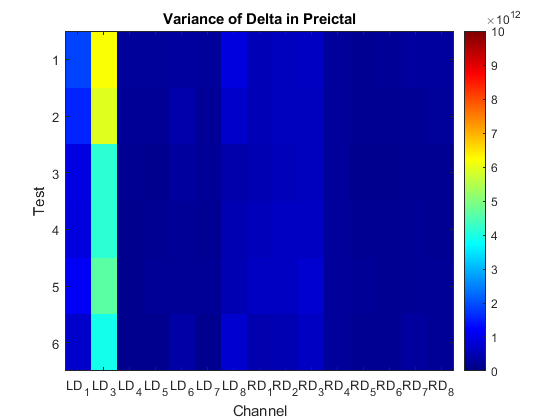


P_fft_Vars = zeros([6 15]);
for i=1:15
    fft_temp_01 = fftshift(abs(fft(P_01_Data(i,:))));
    fft_temp_02 = fftshift(abs(fft(P_02_Data(i,:))));
    fft_temp_03 = fftshift(abs(fft(P_03_Data(i,:))));
    fft_temp_04 = fftshift(abs(fft(P_04_Data(i,:))));
    fft_temp_05 = fftshift(abs(fft(P_05_Data(i,:))));
    fft_temp_06 = fftshift(abs(fft(P_06_Data(i,:))));
    
    P_fft_Vars(1,i) = var(fft_temp_01(1,bottom_bound(brainWave):top_bound(brainWave)));
    P_fft_Vars(2,i) = var(fft_temp_02(1,bottom_bound(brainWave):top_bound(brainWave)));
    P_fft_Vars(3,i) = var(fft_temp_03(1,bottom_bound(brainWave):top_bound(brainWave)));
    P_fft_Vars(4,i) = var(fft_temp_04(1,bottom_bound(brainWave):top_bound(brainWave)));
    P_fft_Vars(5,i) = var(fft_temp_05(1,bottom_bound(brainWave):top_bound(brainWave)));
    P_fft_Vars(6,i) = var(fft_temp_06(1,bottom_bound(brainWave):top_bound(brainWave)));
end

figure
image(P_fft_Vars, 'CDataMapping','scaled')
caxis([0 10000000000000])
colorbar
colormap(jet)
str = sprintf('Variance of %s in Preictal', x_names_str(brainWave));
title(str)
xlabel('Channel')
ylabel('Test')
xticks(1:15)
xticklabels(interictal_segment_9.channels)
yticklabels(1:6)

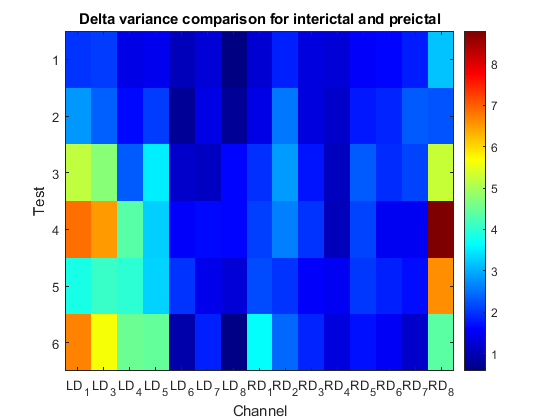


% Variance comparison of Interictal and Preictal

diff_var = zeros([6 15]);

for i = 1:6
    for j = 1:15
        diff_var(i,j) = (I_fft_Vars(i,j)/P_fft_Vars(i,j));
    end
end

figure
image(diff_var, 'CDataMapping','scaled')
colorbar
colormap(jet)
str = sprintf('%s variance comparison for interictal and preictal', x_names_str(brainWave));
title(str)
xlabel('Channel')
ylabel('Test')
xticks(1:15)
xticklabels(interictal_segment_9.channels)
yticklabels(1:6)

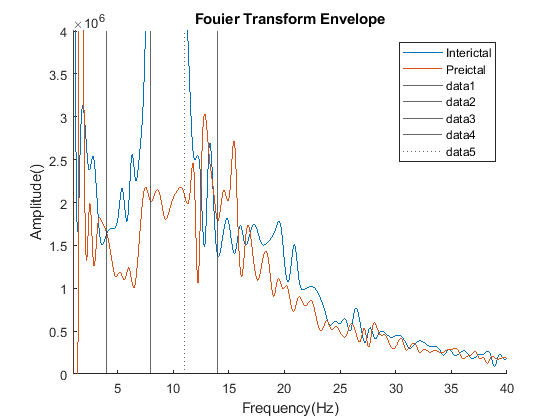

% Envelope - displays a smoother plot

Channel = 5;                                                % Pick data channel (1-15)

I_fft_env = fftshift(abs(fft(I_02_Data(Channel,:))));       % Pick interictal data set
P_fft_env = fftshift(abs(fft(P_02_Data(Channel,:))));       % Pick preictal data set

[I_up,I_lo] = envelope(I_fft_env,200,'peak');
[P_up,P_lo] = envelope(P_fft_env,200,'peak');

figure
hold on
plot(freq,I_up)
plot(freq,P_up)
title('Fouier Transform Envelope')
legend('Interictal', 'Preictal')
xlim([1 40])
ylim([0 4000000])
xline(1)
xline(4)
xline(8)
xline(14)
xline(11,":")
xlabel('Frequency(Hz)'); ylabel('Amplitude()');
hold off